
reconstructedWaveform = predict(autoenc2, testwaveformData);
 
disp("Size of reconstructed waveform:");

Size of reconstructed waveform:


disp(size(reconstructedWaveform));

          15       16000



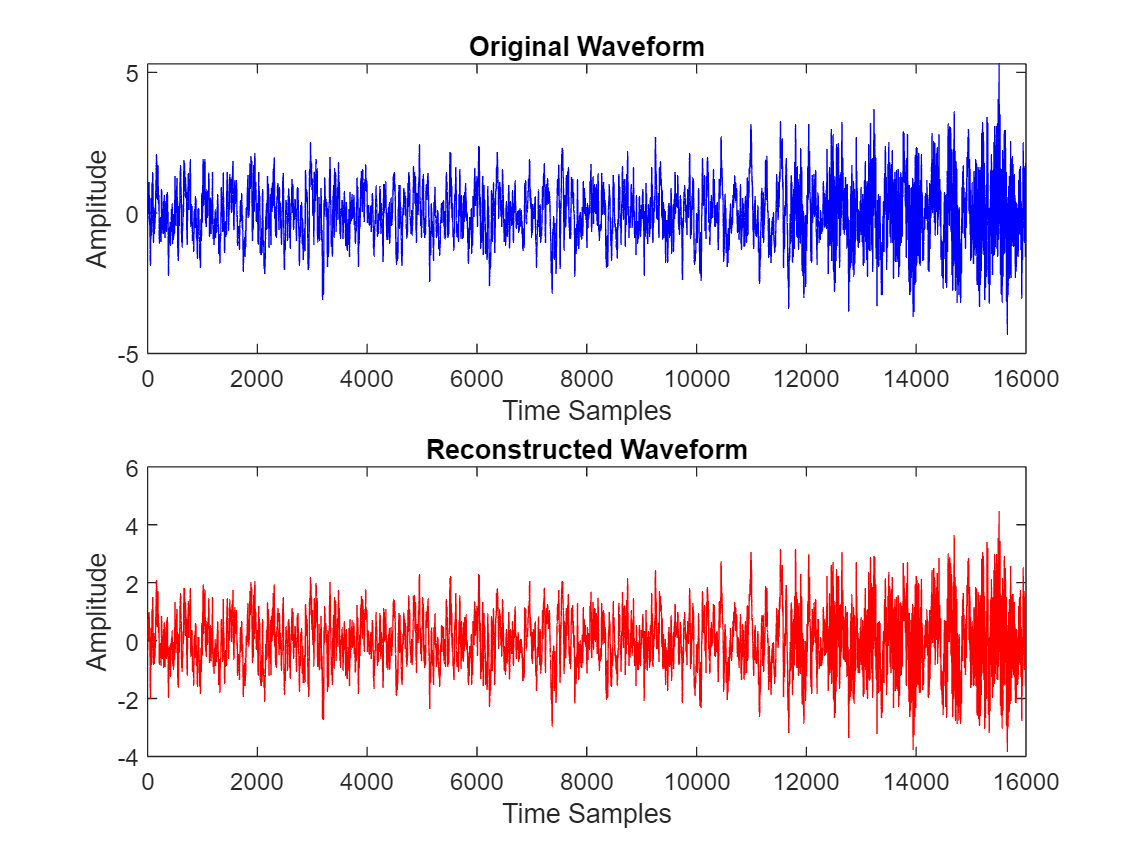

sampleIdx = 4; % Choose a test sample (1-15)

original = testwaveformData(sampleIdx, :);  
reconstructed = reconstructedWaveform(sampleIdx, :);

figure;
subplot(2,1,1);
plot(original, 'b');
title("Original Waveform");
xlabel("Time Samples");
ylabel("Amplitude");

subplot(2,1,2);
plot(reconstructed, 'r');
title("Reconstructed Waveform");
xlabel("Time Samples");
ylabel("Amplitude");

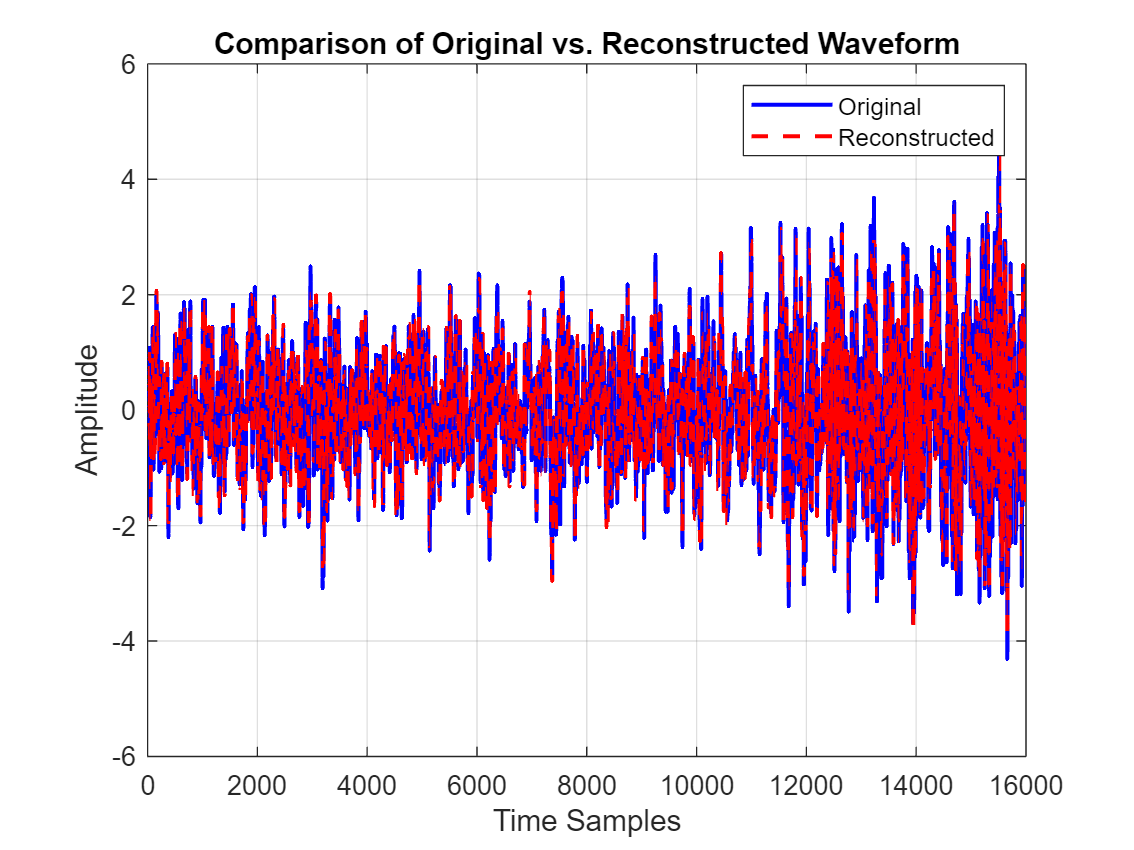


figure;
plot(original, 'b', 'LineWidth', 1.5); hold on;
plot(reconstructed, 'r--', 'LineWidth', 1.5);
legend("Original", "Reconstructed");
title("Comparison of Original vs. Reconstructed Waveform");
xlabel("Time Samples");
ylabel("Amplitude");
grid on;


mseError = mean((original - reconstructed).^2);
fprintf("Mean Squared Error (MSE) for Sample %d: %.6f\n", sampleIdx, mseError);

Mean Squared Error (MSE) for Sample 4: 0.012972
